## The message signals m1(t) 

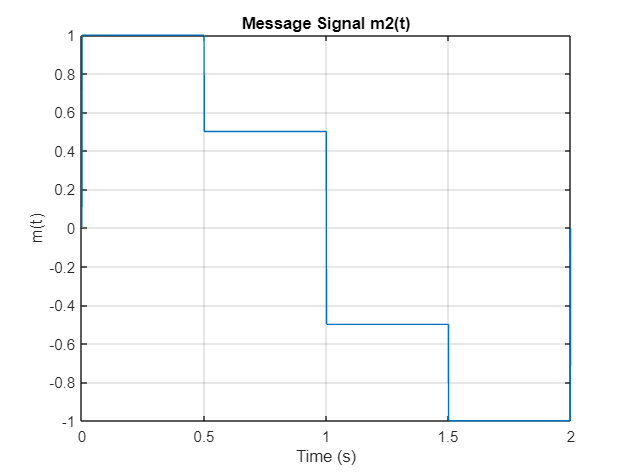

% Message signal data
T_inc = 1/1000;
time = 0:T_inc:2;
% Initialize y array

y = zeros(size(time));
% Generate message signal
for i = 1:length(time)
    if time(i) ==  0
            y(i) = 0 ;
    elseif time(i) > 0 && time(i) <= 0.5
        y(i) = 1 ;
    elseif time(i) > 0.5 && time(i) <= 1
        y(i) = 0.5 ;
    elseif time(i) > 1 && time(i) <= 1.5
        y(i) = -0.5;
    elseif time(i) > 1.5 && time(i) < 2
        y(i) = -1;
    elseif time(i) == 2
        y(i) = 0;
    end
end

% Plotting the signal
msg2 = y;
figure;
plot(time, msg2);
grid on
xlabel('Time (s)');
ylabel('m(t)');
title('Message Signal m2(t)');

##  Modulation

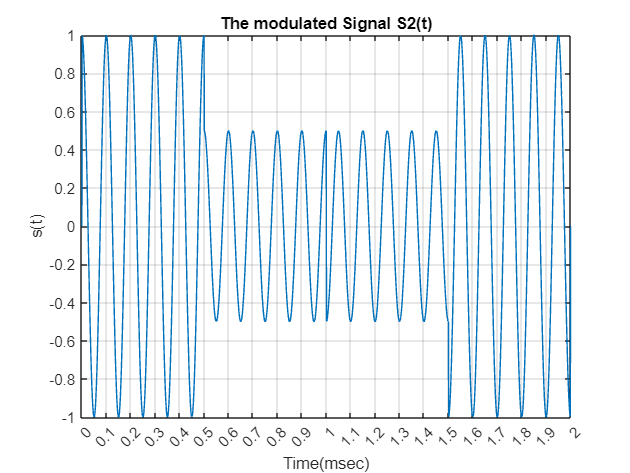

fc = 10;
s2 =  msg2 .* cos(2 * pi * fc * time);
figure;
plot(time, s2);
xticks(0:0.1:2);
grid on
ylabel('s(t)');
xlabel('Time(msec)');
title('The modulated Signal S2(t)');

## Carrier wave Multiplication

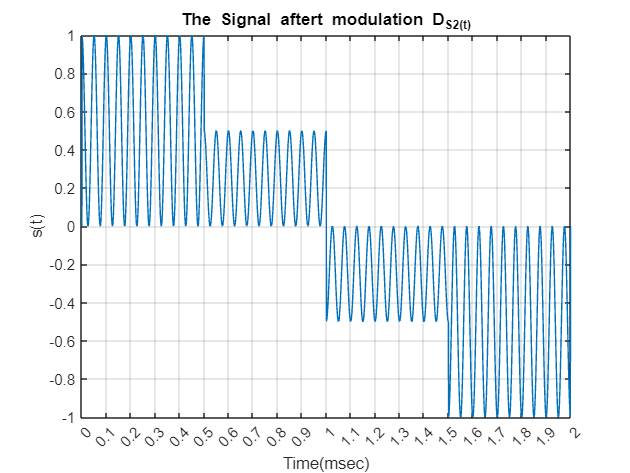

fc = 10;
D_s2 =  s2 .* cos(2 * pi * fc * time);
figure;
plot(time, D_s2);
xticks(0:0.1:2);
grid on
ylabel('s(t)');
xlabel('Time(msec)');
title('The Signal aftert modulation D_S2(t)');

## Signal integration D_S2(t)

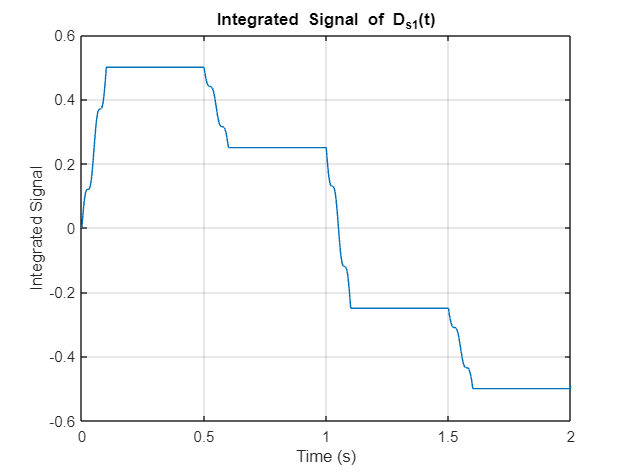

ORD=ones(1,100)/100;
F_Ds2= filter(ORD,1,D_s2);
figure;
plot(time, F_Ds2);
grid on
xlabel('Time (s)');
ylabel('Integrated Signal');
title('Integrated Signal of D_{s1}(t)');